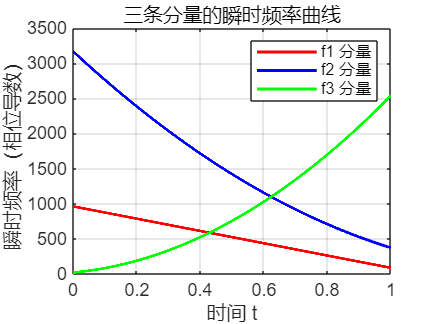

clear; clc; close all;
n = 7000;                
t = linspace(0, 1, n);  
fs = n;                 
win_len = 381;           
nfft = 3000;           
noverlap = win_len-1;  
win = chebwin(win_len, 150);  
phi1 = @(t) (pi /8) * n * ((1-t)+0.1).^2+555;
f1 = @(t) cos(phi1(t));

phi2 = @(t) 0.26 * pi * n * (1.2-0.8*t).^3 -150 * t;
f2 = @(t) sin(phi2(t));

phi3=@(t)(pi/5)* n * (t + 0.1).^3;
f3=@(t)cos(phi3(t));

a11 = @(t) 0.5 * (t + 1);
a21 = @(t) sqrt(1 - t);
a31=@(t)exp(-2*(t-0.4).^2);

phi1_dt = abs(diff(phi1(t)) ./ diff(t)) / (2*pi);
phi2_dt = abs(diff(phi2(t)) ./ diff(t)) / (2*pi);
phi3_dt = diff(phi3(t)) ./ diff(t) / (2*pi);

t_mid = t(1:end-1) + diff(t)/2;

figure;
plot(t_mid, phi1_dt, 'r', 'LineWidth', 1.5); hold on;
plot(t_mid, phi2_dt, 'b', 'LineWidth', 1.5);
plot(t_mid, phi3_dt, 'g', 'LineWidth', 1.5);
xlabel('时间 t');
ylabel('瞬时频率（相位导数）');
title('三条分量的瞬时频率曲线');
legend('f1 分量', 'f2 分量', 'f3 分量');
grid on;

[S1, F1, T1] = spectrogram(f1(t), win, noverlap, nfft, fs);
P1 = abs(S1).^2;
[S2,F2, T2] = spectrogram(f2(t), win, noverlap, nfft, fs);
P2 = abs(S2).^2;
[S3,F3, T3] = spectrogram(f3(t), win, noverlap, nfft, fs);
P3 = abs(S3).^2 

P3 = 1.0e+03 *

    1.6121    1.6425    1.6701    1.6946    1.7160    1.7341    1.7491    1.7607    1.7690    1.7739    1.7754    1.7735    1.7683    1.7598    1.7480    1.7329    1.7146    1.6933    1.6690    1.6417    1.6117    1.5790    1.5437    1.5061    1.4662    1.4242    1.3803    1.3346    1.2873    1.2387    1.1888    1.1379    1.0862    1.0339    0.9811    0.9281    0.8751    0.8222    0.7696    0.7176    0.6663    0.6159    0.5665    0.5185    0.4718    0.4267    0.3833    0.3417    0.3021    0.2646
    1.6293    1.6594    1.6866    1.7108    1.7320    1.7499    1.7646    1.7761    1.7842    1.7891    1.7905    1.7886    1.7835    1.7750    1.7632    1.7482    1.7301    1.7089    1.6848    1.6578    1.6280    1.5955    1.5606    1.5232    1.4836    1.4420    1.3984    1.3531    1.3063    1.2580    1.2085    1.1581    1.1068    1.0548    1.0025    0.9498    0.8972    0.8447    0.7925    0.7408    0.6899    0.6398    0.5908    0.5430    0.4966    0.4518    0.4086    0.3673   

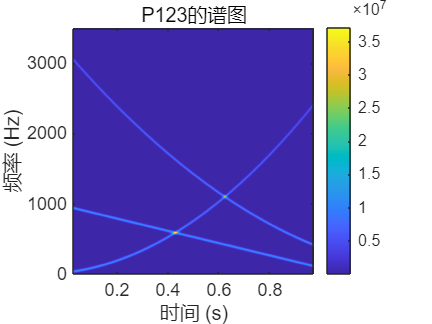

P=abs(P1+P3+P2).^2;
F=F1;
T=T1;
figure;
imagesc(T1, F1, P); 
axis xy;
xlabel('时间 (s)');
ylabel('频率 (Hz)');
title('P123的谱图');
colorbar;


num_peaks   = zeros(1, length(T1));     
peak_freqs  = cell(1, length(T1));      
peak_vals   = cell(1, length(T1));      
for i = 1:length(T1)
    p_slice = P(:, i);
    [peaks, locs] = findpeaks(p_slice, 'MinPeakHeight', 5);
    num_peaks(i) = length(peaks);
    peak_freqs{i} = F(locs);
    peak_vals{i}  = peaks;  
end

single_peak2_times     = T1(num_peaks == 2)

single_peak2_times =     0.4152    0.4154    0.4155    0.4156    0.4158    0.4159    0.4161    0.4162    0.4164    0.4165    0.4166    0.4168    0.4169    0.4171    0.4172    0.4174    0.4175    0.4176    0.4178    0.4179    0.4181    0.4182    0.4184    0.4185    0.4186    0.4188    0.4189    0.4191    0.4192    0.4194    0.4195    0.4196    0.4198    0.4199    0.4201    0.4202    0.4204    0.4205    0.4206    0.4208    0.4209    0.4211    0.4212    0.4214    0.4215    0.4216    0.4218    0.4219    0.4221    0.4222


single_peak2_freqs     = peak_freqs(num_peaks == 2)

single_peak2_freqs = 1×308 cell 数组
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {

single_peak2_strengths = peak_vals(num_peaks == 2)

single_peak2_strengths = 1×308 cell 数组
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double} 


single_peak3_times     = T1(num_peaks == 3)

single_peak3_times =     0.0272    0.0274    0.0275    0.0276    0.0278    0.0279    0.0281    0.0282    0.0284    0.0285    0.0286    0.0288    0.0289    0.0291    0.0292    0.0294    0.0295    0.0296    0.0298    0.0299    0.0301    0.0302    0.0304    0.0305    0.0306    0.0308    0.0309    0.0311    0.0312    0.0314    0.0315    0.0316    0.0318    0.0319    0.0321    0.0322    0.0324    0.0325    0.0326    0.0328    0.0329    0.0331    0.0332    0.0334    0.0335    0.0336    0.0338    0.0339    0.0341    0.0342


single_peak3_freqs     = peak_freqs(num_peaks == 3)

single_peak3_freqs = 1×6312 cell 数组
  列 1 至 2047

    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3

single_peak3_strengths = peak_vals(num_peaks == 3)

single_peak3_strengths = 1×6312 cell 数组
  列 1 至 2047

    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}  

find_crossings = @(a,b,t) deal( ...
    interp1(sign(a - b), t, 0, 'linear', 'extrap'), ...
    interp1(sign(a - b), a, 0, 'linear', 'extrap') ...
);
idx13 = find(diff(sign(phi1_dt- phi3_dt)) ~= 0);
t_cross13 = t_mid(idx13)

t_cross13 = 0.4287

f_cross13 = (phi1_dt(idx13) + phi3_dt(idx13)) / 2;
idx23 = find(diff(sign(phi2_dt - phi3_dt)) ~= 0);
t_cross23 = t_mid(idx23)

t_cross23 = 0.6232

f_cross23 = ( phi2_dt(idx23) + phi3_dt(idx23)) / 2;

times = single_peak2_times(:);  
times = sort(times);        
freqs = single_peak2_freqs(:); 
strength=single_peak2_strengths(:);
time_diff = diff(times);
split_idx = find(time_diff > 0.01);

section21_times = times(1:split_idx(1));
section22_times = times(split_idx(1)+1:end);
section21_strength = strength(1:split_idx(1));
section22_strength = strength(split_idx(1)+1:end);
section21_freqs = freqs(1:split_idx(1));
section22_freqs = freqs(split_idx(1)+1:end);
times = single_peak3_times(:);  
times = sort(times);           
freqs = single_peak3_freqs(:); 
strength = single_peak3_strengths(:);
time_diff = diff(times);
split_idx = find(time_diff > 0.001);
section1_times = times(1:split_idx(1))

section1_times =     0.0272
    0.0274
    0.0275
    0.0276
    0.0278
    0.0279
    0.0281
    0.0282
    0.0284
    0.0285


section2_times = times(split_idx(1)+1:split_idx(2))

section2_times =     0.4425
    0.4426
    0.4428
    0.4429
    0.4431
    0.4432
    0.4434
    0.4435
    0.4436
    0.4438


section3_times = times(split_idx(2)+1:end)

section3_times =     0.6316
    0.6318
    0.6319
    0.6321
    0.6322
    0.6324
    0.6325
    0.6326
    0.6328
    0.6329


section1_strength = strength(1:split_idx(1))

section1_strength = 2716×1 cell 数组
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}


section2_strength = strength(split_idx(1)+1:split_idx(2));
section3_strength = strength(split_idx(2)+1:end);
section1_freqs = freqs(1:split_idx(1))

section1_freqs = 2716×1 cell 数组
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}
    {3×1 double}


section2_freqs = freqs(split_idx(1)+1:split_idx(2));
section3_freqs = freqs(split_idx(2)+1:end);
[dominant_strength1, dominant_freq1,nondom_freq1, ~] = extract_dominant_strength_column(section21_strength, section21_freqs);
dominant_time1 = section21_times;
[dominant_strength2, dominant_freq2,nondom_freq2, ~] = extract_dominant_strength_column(section22_strength, section22_freqs);
dominant_time2 = section22_times;
res_1=pickPointsByTimeRange(P, F1, T1,dominant_time1,dominant_freq1,'WindowRatio',1);
X_11=res_1.xi1_1

X_11 =   567.0000
  567.0000
  567.0000
  567.0000
  569.3333
  569.3333
  588.0000
  588.0000
  585.6667
  585.6667


X_12=res_1.xi1_2

X_12 =   597.3333
  597.3333
  595.0000
  595.0000
  595.0000
  595.0000
  595.0000
  595.0000
  592.6667
  592.6667


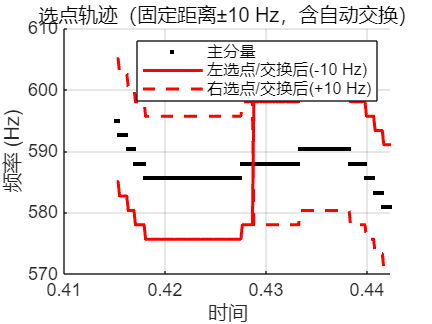

dominant_time11 = dominant_time1(:);
dominant_freq11 = dominant_freq1(:);
swap_idx = find(dominant_time11 >= t_cross13, 1);
if ~isempty(swap_idx)
    temp = X_11(swap_idx:end);
    X_11(swap_idx:end) = X_12(swap_idx:end);
    X_12(swap_idx:end) = temp;
end
[xi1_11, xi1_12] = plotSegmentPickedTracksSimple(dominant_time1, dominant_freq1, t_cross13, 10);

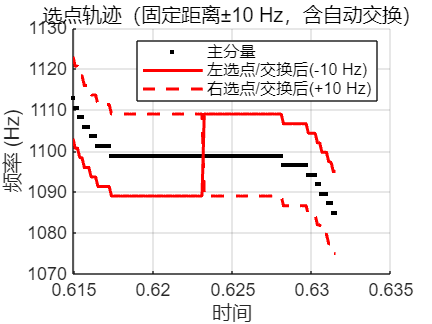

[xi1_21, xi1_22] = plotSegmentPickedTracksSimple(dominant_time2, dominant_freq2, t_cross23, 10);

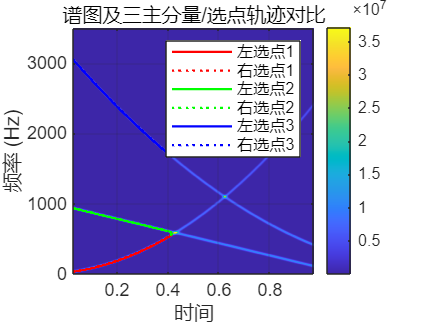

[freqs1, xi_left1, xi_right1] = extractThreeTracksWithPickedPoints(section1_times, section1_freqs, T1, P, F1);

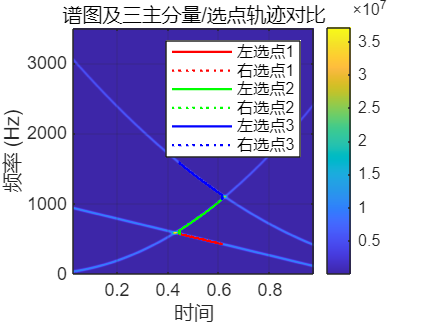

[freqs2, xi_left2, xi_right2] = extractThreeTracksWithPickedPoints(section2_times, section2_freqs, T1, P, F1);

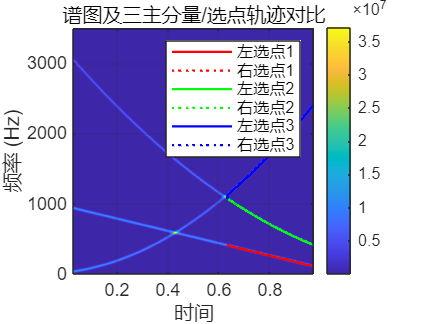

[freqs3, xi_left3, xi_right3] = extractThreeTracksWithPickedPoints(section3_times, section3_freqs, T1, P, F1);

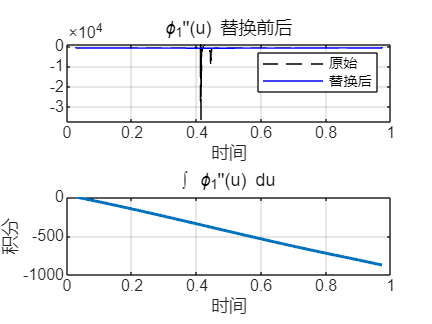


res1= pickPointsByTimeRange(P, F1, T1, dominant_time1, nondom_freq1, 'WindowRatio', 1);
res2= pickPointsByTimeRange(P, F1, T1, dominant_time2, nondom_freq2, 'WindowRatio', 1);
r2_r=[xi_right1(:,1);xi1_12;xi_right2(:,2);xi1_22;xi_right3(:,3)];
r2_r=r2_r';
r2_l=[xi_left1(:,1);xi1_11;xi_left2(:,2);xi1_21;xi_left3(:,3)];
r2_l=r2_l';

r1_r=[xi_right1(:,2);xi1_12;xi_right2(:,1);res2.xi1_2;xi_right3(:,1)];
r1_r=r1_r';
r1_l=[xi_left1(:,2);xi1_11;xi_left2(:,1);res2.xi1_1;xi_left3(:,1)];
r1_l=r1_l';

r3_l=[xi_left1(:,3);res1.xi1_1;xi_left2(:,3);xi1_21;xi_left3(:,2)]';
r3_r=[xi_right1(:,3);res1.xi1_2;xi_right2(:,3);xi1_22;xi_right3(:,2)]';
dF = mean(diff(F));
dT = mean(diff(T)); 
kernel = [1 0 -1]/2;
P_xi = conv2(P, kernel', 'same') / dF; 
P_u  = conv2(P, kernel,  'same') / dT;
est1 = Phi1Estimator(F, T, P, P_u, P_xi);
est1_1 = Phi1Estimator4(F, T, P, P_u, P_xi);
phi1_1_2nd = est1_1.computeSecondDerivative(r1_r, r1_l);
phi1_1_2nd_updated = est1_1.smoothSections(phi1_1_2nd, section1_times, section2_times, 0.25);
CR1_1_integrated = est1_1.tvSmoothAndIntegrate(phi1_1_2nd_updated);
est1_1.plotAll(T, phi1_1_2nd, phi1_1_2nd_updated, CR1_1_integrated);

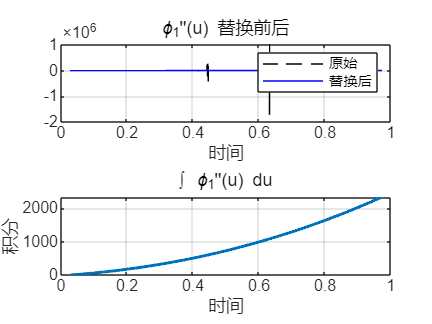

x_int = linspace(0, 1, 66200);
x_dt  = linspace(0, 1, 7000-1);
est2_1 = Phi1Estimator4(F, T, P, P_u, P_xi);
phi2_1_2nd = est2_1.computeSecondDerivative(r2_r, r2_l);
phi2_1_2nd_updated = est2_1.smoothSections(phi2_1_2nd, section1_times, section3_times, 0.1);
CR2_1_integrated = est2_1.tvSmoothAndIntegrate(phi2_1_2nd_updated);
est2_1.plotAll(T, phi2_1_2nd, phi2_1_2nd_updated, CR2_1_integrated);

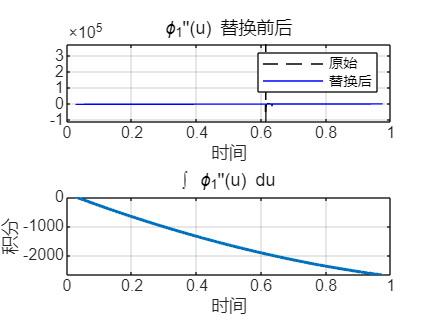

x_int = linspace(0, 1, 66200);
x_dt  = linspace(0, 1, 7000-1);
est3_3= Phi1Estimator4(F, T, P, P_u, P_xi);
phi3_3_2nd = est3_3.computeSecondDerivative(r3_r, r3_l);
phi3_3_2nd_updated = est3_3.smoothSections(phi3_3_2nd, section2_times, section3_times, 0.3);
CR3_3_integrated = est3_3.movmeanSmoothAndIntegrate(phi3_3_2nd_updated);
est3_3.plotAll(T, phi3_3_2nd, phi3_3_2nd_updated, CR3_3_integrated);

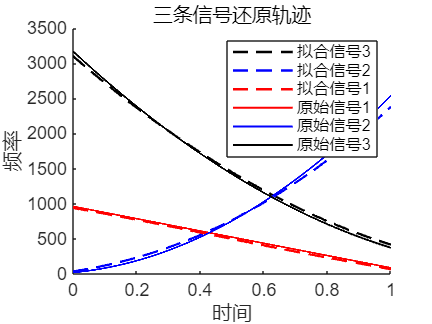

x_int = linspace(0, 1, 66200);
x_dt  = linspace(0, 1, 7000-1);
x_int = linspace(0, 1, 66200);
x_dt  = linspace(0, 1, 7000-1);
figure;
hold on;
plot(x_int,CR3_3_integrated'+3100,'--k','LineWidth',1.2);
plot(x_int,CR2_1_integrated+38,'--b','LineWidth',1.2);
plot(x_int,CR1_1_integrated+940,'--r','LineWidth',1.2);
plot(x_dt,  phi1_dt,         '-r', 'LineWidth', 1, 'DisplayName', 'phi2\_dt');
plot(x_dt,  phi3_dt,         '-b', 'LineWidth', 1, 'DisplayName', 'phi2\_dt');
plot(x_dt,  phi2_dt,         '-k', 'LineWidth', 1, 'DisplayName', 'phi2\_dt');
ylabel("频率", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
title("三条信号还原轨迹")
xlabel("时间", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")

legend(["拟合信号3", "拟合信号2", "拟合信号1", "原始信号1", "原始信号2", "原始信号3"])


function [dominant_strength, dominant_freq, ...
          nondom_freq,nondom_strength,  ...
          indices] = extract_dominant_strength_column(strength_cell, freq_cell)
    strength_mat = cell2mat(strength_cell);
    strength_matrix = reshape(strength_mat, 2, []).';

    freq_mat = cell2mat(freq_cell);
    freq_matrix = reshape(freq_mat, 2, []).';
    range1 = max(strength_matrix(:,1)) - min(strength_matrix(:,1));
    range2 = max(strength_matrix(:,2)) - min(strength_matrix(:,2));

    if range1 >= range2
        dominant_strength = strength_matrix(:,1);
        dominant_freq     = freq_matrix(:,1);

        nondom_strength   = strength_matrix(:,2);
        nondom_freq       = freq_matrix(:,2);

        indices = 1;
    else
        dominant_strength = strength_matrix(:,2);
        dominant_freq     = freq_matrix(:,2);

        nondom_strength   = strength_matrix(:,1);
        nondom_freq       = freq_matrix(:,1);

        indices = 2;
    end
end

function results = pickPointsByTimeRange(P, F, T, times, freqs, varargin)

N = numel(times);
xi1_1 = NaN(N,1);
xi1_2 = NaN(N,1);
frame_times = NaN(N,1);
main_freqs = NaN(N,1);

for i = 1:N
    [~, k] = min(abs(T - times(i)));
    spec_k = P(:, k);
    freq = freqs(i);
    [~, peak_idx] = min(abs(F - freq));
    result = selectPointsBySlope1PeakAdaptive('P', spec_k, ...
                                              'F', F, ...
                                              'PeakIdx', peak_idx, ...
                                              varargin{:});
    xi1_1(i) = result.xi1_1;
    xi1_2(i) = result.xi1_2;
    frame_times(i) = T(k);
    main_freqs(i) = freq;
end

results.times = frame_times;
results.main_freqs = main_freqs;
results.xi1_1 = xi1_1;
results.xi1_2 = xi1_2;
end

function [xi1_11, xi1_12] = plotSegmentPickedTracksSimple(dominant_time, dominant_freq, u_cross, delta_f)

dominant_time = dominant_time(:);
dominant_freq = dominant_freq(:);
xi1_11 = dominant_freq - delta_f;
xi1_12 = dominant_freq + delta_f;

swap_idx = find(dominant_time >= u_cross, 1);
if ~isempty(swap_idx)
    temp = xi1_11(swap_idx:end);
    xi1_11(swap_idx:end) = xi1_12(swap_idx:end);
    xi1_12(swap_idx:end) = temp;
end

figure;
hold on; grid on;
xlabel('时间');
ylabel('频率 (Hz)');
title(['选点轨迹（固定距离±' num2str(delta_f) ' Hz，含自动交换）']);
plot(dominant_time, dominant_freq, 'k.', 'DisplayName', '主分量');
plot(dominant_time, xi1_11, 'r-', 'LineWidth', 1.5, 'DisplayName', ['左选点/交换后(-' num2str(delta_f) ' Hz)']);
plot(dominant_time, xi1_12, 'r--', 'LineWidth', 1.5, 'DisplayName', ['右选点/交换后(+' num2str(delta_f) ' Hz)']);
legend show;
end

function [freqs, xi_left, xi_right] = extractThreeTracksWithPickedPoints(section_times, section_freqs, T1, P, F1)

N = numel(section_times);
freqs = zeros(N,3);         
xi_left = NaN(N,3);         
xi_right = NaN(N,3);       
for i = 1:N
    fvec = sort(section_freqs{i});
    freqs(i,:) = fvec(:)';
    [~, k] = min(abs(T1 - section_times(i)));
    spec_k = P(:, k);
    F = F1;

    for j = 1:3
        [~, peak_idx] = min(abs(F - fvec(j)));
        result = selectPointsBySlope1PeakAdaptive('P', spec_k, ...
                                                  'F', F, ...
                                                  'PeakIdx', peak_idx, ...
                                                  'WindowRatio', 1.0); 
        xi_left(i, j) = result.xi1_1;
        xi_right(i, j) = result.xi1_2;
    end
end

figure;
imagesc(T1, F1, P);
axis xy; hold on; grid on;
xlabel('时间'); ylabel('频率 (Hz)');
title('谱图及三主分量/选点轨迹对比');
colorbar;

color_map = {'r','g','b'};
for j = 1:3
    plot(section_times, xi_left(:,j), [color_map{j} '-'], 'LineWidth', 1.1, 'DisplayName', ['左选点' num2str(j)]);
    plot(section_times, xi_right(:,j), [color_map{j} ':'], 'LineWidth', 1.1, 'DisplayName', ['右选点' num2str(j)]);
end
legend show;
end